A=double(imread('img2.png')); 
A=A/255;

size_img=size(A);

%Preparing our feature matrix X by reshaping the pixel matrix A
X=reshape(A,size_img(1)*size_img(2),3);
%Each row displays R,G and B pixel values

K=16;
max_iters=10;

initial_centroids=initCentroids(X,K);
[centroids, ~] = runAlgo_Kmeans(X, initial_centroids, max_iters);

% Find closest cluster members
idx =ClosestCentroid(X, centroids);

X_recovered = centroids(idx,:); %recovering the image by mapping each pixel to the centroid value

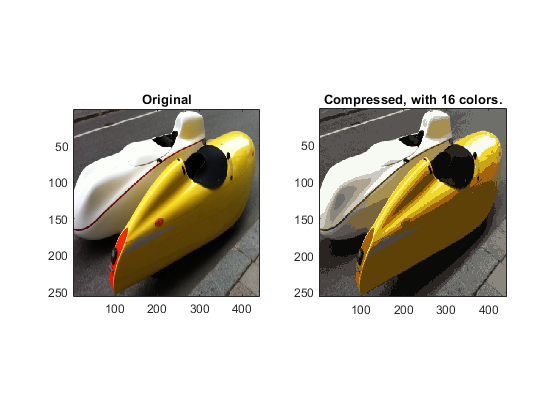

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, size_img(1),size_img(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square